# load the data

T = readtable('data_15870_6.csv');

## The order of the data is

% (time,x,y,speed,theta,u,delta)
time = T{:,1};
x = T{:,2};
y = T{:,3};
speed = T{:,4};
theta = T{:,5};
u = T{:,6};
delta = T{:,7};

% create the input and output matrices

output = {x,y,speed,theta};
output = cell2mat(output);


input = {u,delta};
input = cell2mat(input);

% Create iddata object

data = iddata(output,input,0.01);
data.OutputName ={'x';'y';'speed';'theta'};
data.InputName ={'u';'delta'};
data.Intersample = {'foh';'foh'};

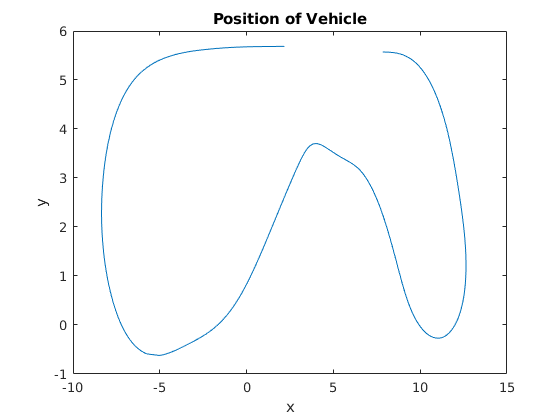

% Let's look at the postion data we have
figure();
plot(x,y);
xlabel('x') 
ylabel('y') 
title("Position of Vehicle")

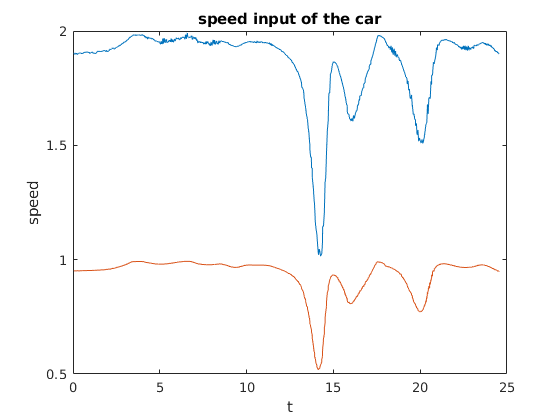

% Let's look at the angle and input data we have 
figure();
plot(time,speed);
hold on;
plot(time, u);
xlabel('t') 
ylabel('speed') 
title("speed input of the car")

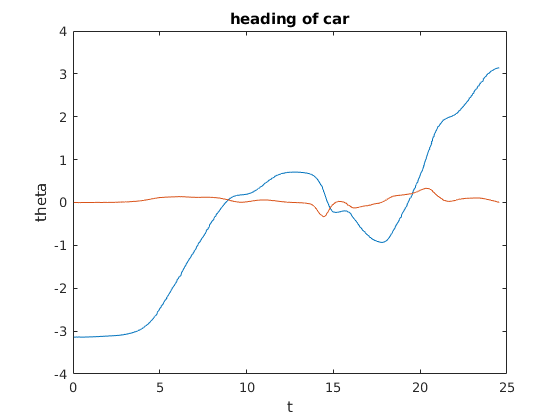

% Let's look at the angle and input data we have 
figure();
plot(time,theta);
hold on;
plot(time, delta);
xlabel('t') 
ylabel('theta') 
title("heading of car")

% Let's try the system identification now

% specify the initial parameters
 ca = 31.08;
 cm = -9.175; 
 ch = 1.4077;
 lf = 0.5;%0.255;
 lr = 0.3;%0.225;

% not sure why they call it order
% it species the number of model outputs
% the model inputs, and states
% so for us its 2 inputs, 4 outputs, 4 states

order         = [4 2 4];
parameters    = {ca,cm,ch,lf,lr};
initial_states = [0; 0;0;0];
Ts = 0;
nonlinear_model = idnlgrey('bicycle_model',order,parameters,initial_states,Ts);
nonlinear_model.algorithm.SimulationOptions.Solver = 'ode45';
nonlinear_model.algorithm.SimulationOptions.MaxStep = 1e-1;
nonlinear_model.algorithm.SimulationOptions.InitialStep = 1e-4;
nonlinear_model.SimulationOptions.AbsTol = 1e-6;
nonlinear_model.SimulationOptions.RelTol = 1e-5;
setpar(nonlinear_model,'Fixed',{false, false,false,true,true});

% Do the estimation 
opt = nlgreyestOptions;
opt.Display = 'Full';
opt.SearchOptions.FunctionTolerance = 1e-10;
opt.SearchOptions.MaxIterations = 100;
nonlinear_model = nlgreyest(data,nonlinear_model,opt);

% get the parameters
b_est = nonlinear_model.Parameters

b_est = 5×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


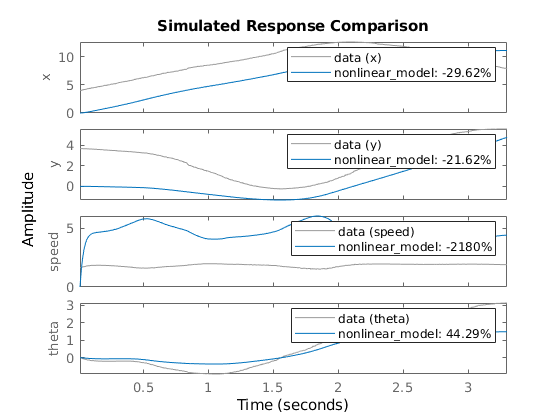

% compare the learned model to the data 
figure();

compare(data,nonlinear_model)